imagen_original = imread('vaca.jpg');
tamano = size(imagen_original)

tamano =    607   910     3


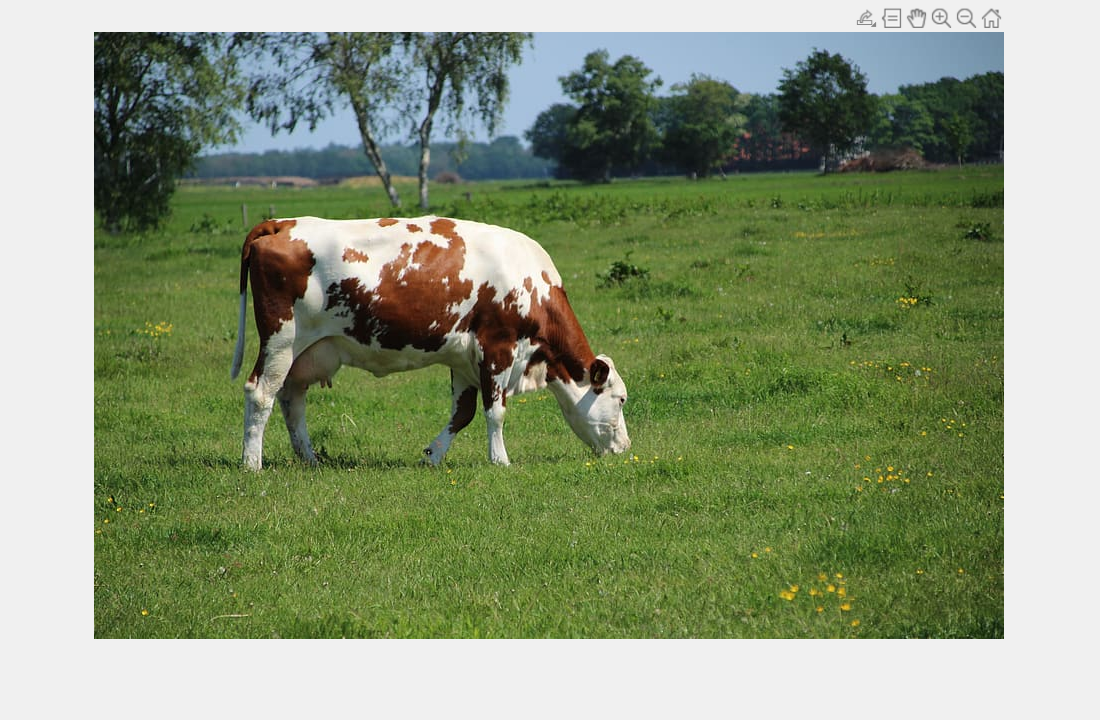

imshow(imagen_original)
rect = getrect; %x, y, w, h

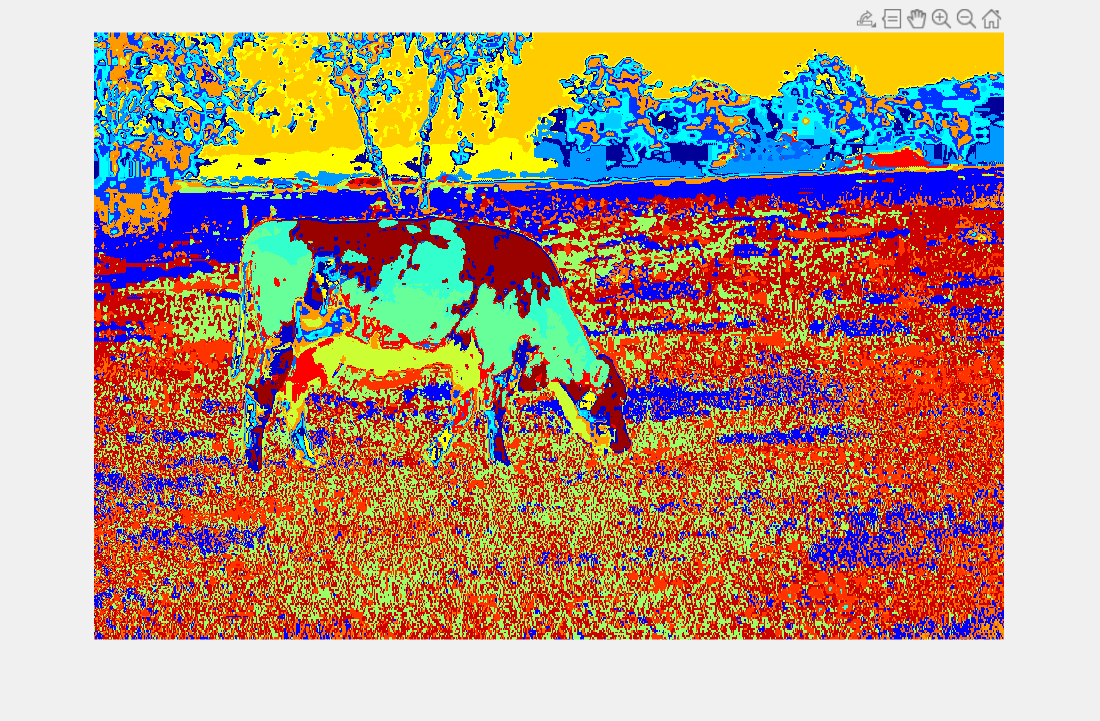

HSV = rgb2hsv(imagen_original);
[f, c, w] = size(HSV);

Hue = HSV(:, :, 1) * 2 * pi;  %|Hy/H
Huex = cos(Hue);              %| /
Huey = sin(Hue);              %|/__________Hx

S = HSV(:, :, 2);
V = HSV(:, :, 3);

Hx = reshape(Huex, [tamano(1) * tamano(2), 1]);
Hy = reshape(Huey, [tamano(1) * tamano(2), 1]);
S = reshape(S, [tamano(1) * tamano(2), 1]);
V = reshape(V, [tamano(1) * tamano(2), 1]);

O = [Hx Hy S V];
k = 20;

C = kmeans(O, k);

IC = reshape(C,f,c); 
rgb = label2rgb(IC); 
imshow(rgb);

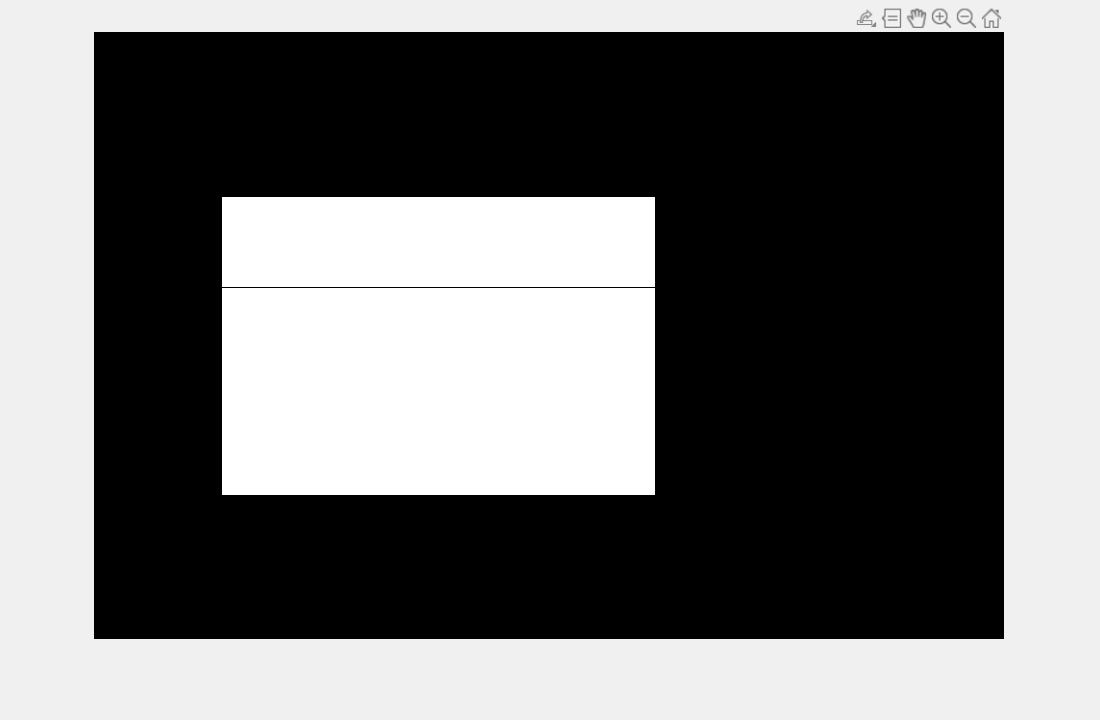

MASK = false(f, c);
MASK(floor(rect(2):rect(2)+rect(4)), floor(rect(1):rect(1)+rect(3))) = true;
imshow(MASK);

H = [C, MASK(:)];
Hist0 = zeros(1, k);
Hist1 = zeros(1, k);

for i = 1:f*c
    pos = H(i, 1);
    res = H(i, 2);
    
    if res
        Hist1(pos) = Hist1(pos) + 1;
    else
        Hist0(pos) = Hist0(pos) + 1;
    end
    
end

RES = Hist1 > Hist0;

M = zeros(f*c, 1);
for i = 1:f*c
    pos = H(i, 1);
    if RES(pos)
        M(i) = 1;
    end
end
M = reshape(M, [f, c]);

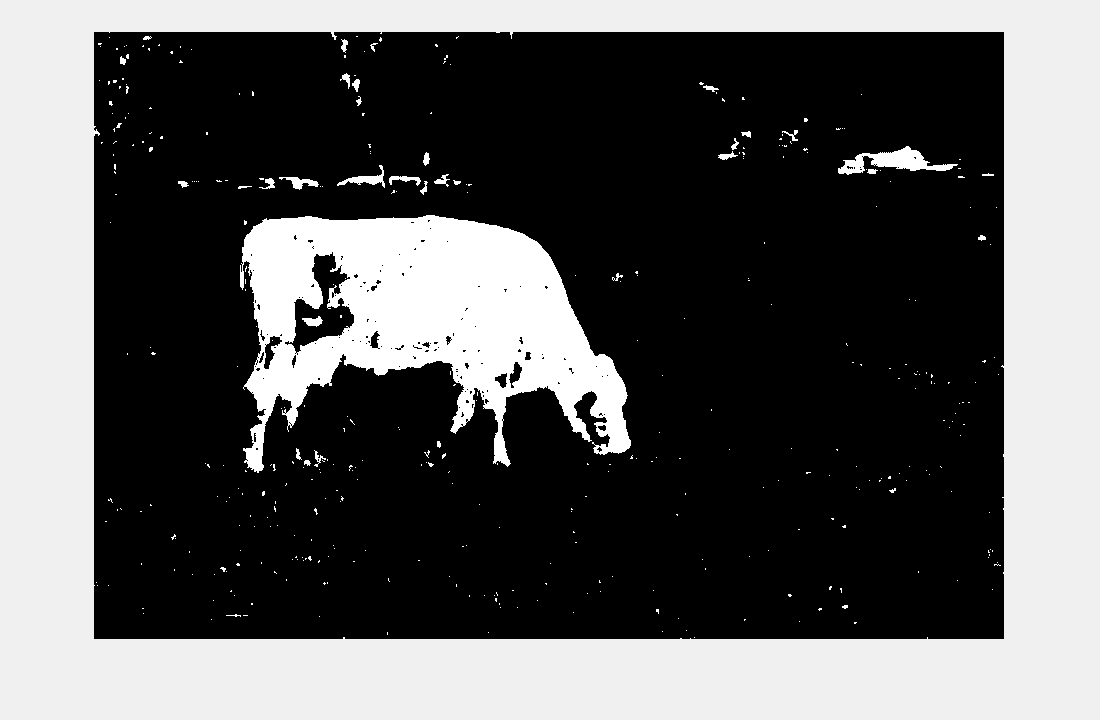

imshow(M);

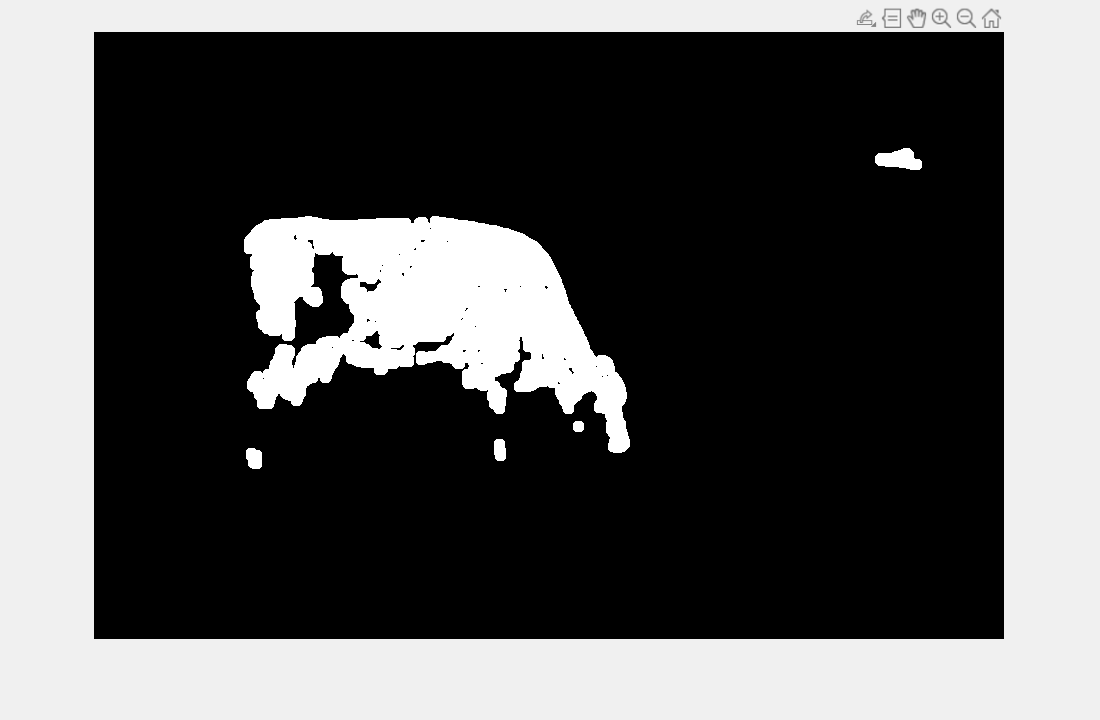

SE = strel('disk', 6);
imagen_cerrada = imopen(M, SE);
imshow(imagen_cerrada);

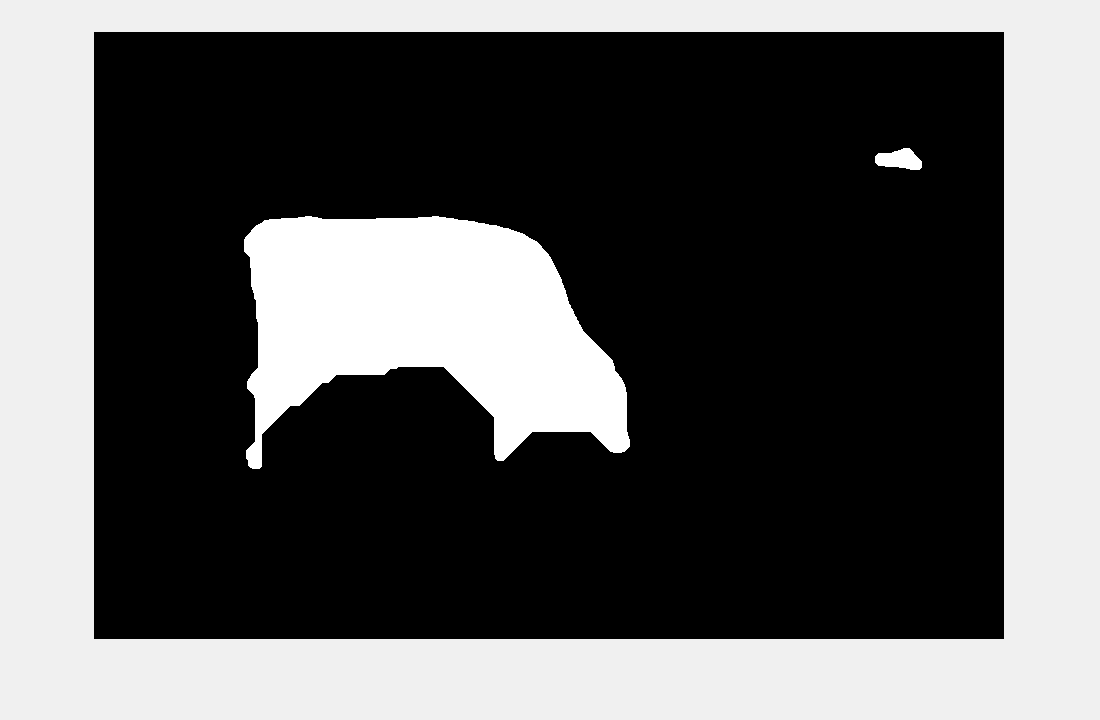


SE1 = strel('disk', 50);
imagen_cerrada = imclose(imagen_cerrada, SE1);
imshow(imagen_cerrada);

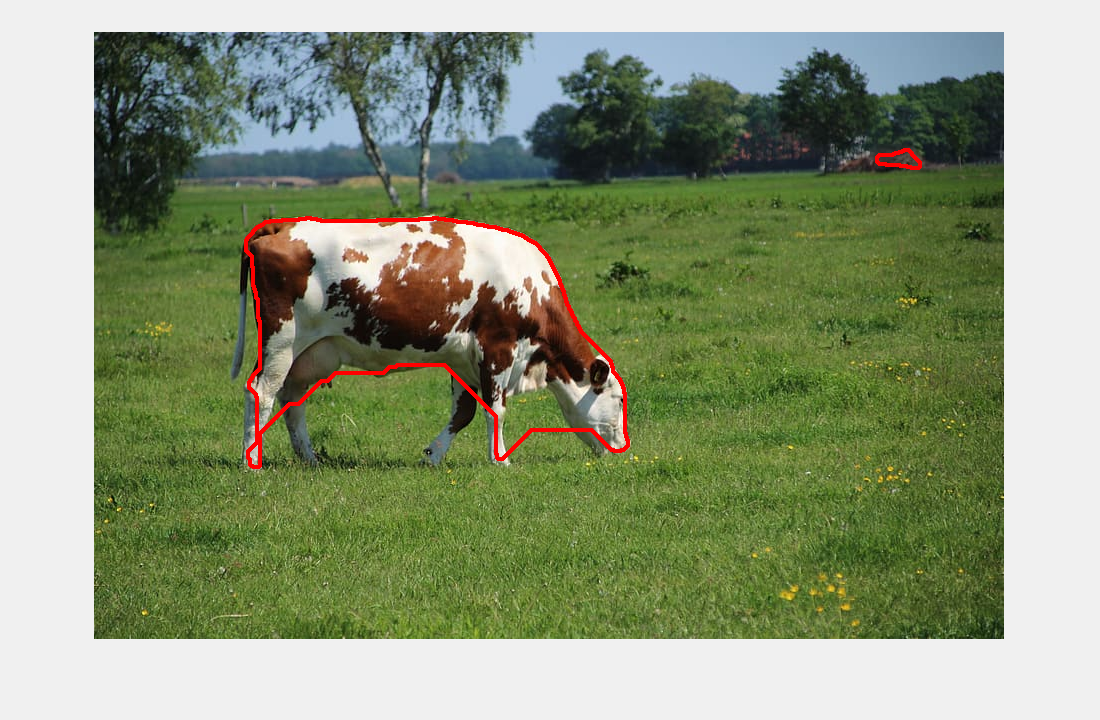

disk = strel('disk',5);
imagen_casi_bordes = imerode(imagen_cerrada,disk);

bordes = imagen_cerrada - imagen_casi_bordes;

I = imoverlay(imagen_original, bordes, 'red');
imshow(I);